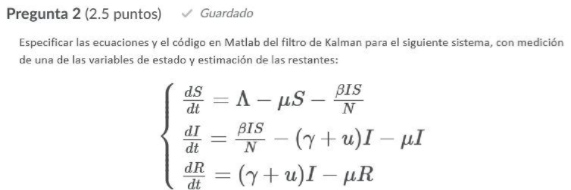

% Sistema no lineal continuo modelado en espacio de estado
syms x1 x2 x3 u % x1 = S, x2 = I, x3 = R

Alpha = 0.05;
mu = 0.01;
beta= 0.05;
gamma = 0.07;


% Imprimir ecuaciones de estado
N = x1 + x2 + x3;
ode1 = Alpha - mu*x1 - beta*x2*x1/N;
ode2 = beta*x2*x1/N - (gamma+u)*x2 -mu*x2;
ode3 = (gamma+u)*x2 - mu*x3;

% Vector de estado
odes = [ode1; ode2; ode3]

$$odes = \left(\begin{array}{c} \frac{1}{20}-\frac{x_{1}\,x_{2}}{20\,\left(x_{3}+x_{2}+x_{1}\right)}-\frac{x_{1}}{100}\\ \frac{x_{1}\,x_{2}}{20\,\left(x_{3}+x_{2}+x_{1}\right)}-x_{2}\,\left(\frac{7}{100}+u\right)-\frac{x_{2}}{100}\\ x_{2}\,\left(\frac{7}{100}+u\right)-\frac{x_{3}}{100} \end{array}\right)$$


% Variables
vars = [x1 x2 x3];

% Imprimir jacobiano
A = jacobian(odes, vars)

$$A = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1}-\frac{x_{2}}{20\,\left(x_{3}+x_{2}+x_{1}\right)}-\frac{1}{100} & \sigma_{1}-\frac{x_{1}}{20\,\left(x_{3}+x_{2}+x_{1}\right)} & \sigma_{1}\\ \frac{x_{2}}{20\,\left(x_{3}+x_{2}+x_{1}\right)}-\sigma_{1} & \frac{x_{1}}{20\,\left(x_{3}+x_{2}+x_{1}\right)}-u-\sigma_{1}-\frac{2}{25} & -\sigma_{1}\\ 0 & \frac{7}{100}+u & -\frac{1}{100} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{x_{1}\,x_{2}}{20\,{\left(x_{3}+x_{2}+x_{1}\right)}^{2}} \end{array}$$


% Matriz C conocida
C = [1, 0, 0]

C =      1     0     0




% Discretización y linealización

% Muestreo
t0 = 0; % Tiempo inicial
step = 0.1; % Tamaño de paso
tf = 1000; % Tiempo final (tiempo de muestreo)

tspan = t0:step:tf; % Vector de tiempo discreto

% Cambiar: Entrada para simular
u = ones(1, length(tspan)); 

% condiciones iniciales [x1(0), x2(0), ..., xn(0)]
x0 = [1000;100;200];

[t, x_sim, y_sim, U] = solve_ode(tspan,x0, u, C);
% x_sim: solución del sistema (estados) que da el solver
% y_sim: salida del sistema que da el solver

% Filtro de Kalman extendido

A = matlabFunction(A)

A = function_handle with value:
    @(u,x1,x2,x3)reshape([(x2.*(-1.0./2.0e+1))./(x1+x2+x3)+(x1.*x2.*1.0./(x1+x2+x3).^2)./2.0e+1-1.0./1.0e+2,x2./(x1.*2.0e+1+x2.*2.0e+1+x3.*2.0e+1)-(x1.*x2.*1.0./(x1+x2+x3).^2)./2.0e+1,0.0,(x1.*(-1.0./2.0e+1))./(x1+x2+x3)+(x1.*x2.*1.0./(x1+x2+x3).^2)./2.0e+1,-u+x1./(x1.*2.0e+1+x2.*2.0e+1+x3.*2.0e+1)-(x1.*x2.*1.0./(x1+x2+x3).^2)./2.0e+1-2.0./2.5e+1,u+7.0./1.0e+2,(x1.*x2.*1.0./(x1+x2+x3).^2)./2.0e+1,x1.*x2.*1.0./(x1+x2+x3).^2.*(-1.0./2.0e+1),-1.0./1.0e+2],[3,3])


f = matlabFunction(odes)

f = function_handle with value:
    @(u,x1,x2,x3)[x1.*(-1.0./1.0e+2)-(x1.*x2)./(x1.*2.0e+1+x2.*2.0e+1+x3.*2.0e+1)+1.0./2.0e+1;x2.*(-1.0./1.0e+2)-x2.*(u+7.0./1.0e+2)+(x1.*x2)./(x1.*2.0e+1+x2.*2.0e+1+x3.*2.0e+1);x3.*(-1.0./1.0e+2)+x2.*(u+7.0./1.0e+2)]


I = eye(length(vars));
M = 0.01*I; % Se elige heurísticamente
N = 0.0025; % Se elige heurísticamente
V = I; % Lo usual

n = length(y_sim); % número de datos

% Predicción (time update)
x_pre = x0; % x_hat(k+1|k)
P_pre = M; % P_bar(k+1), matriz de cov intermedia

% Convergencia
norma_K = zeros(n-1, 1); % Vector de norma de K en cada iteración
x_hat = zeros(n-1, length(vars)); % Estimación de estados
traza_P = zeros(n-1, 1); % Vector de traza de P en cada iteración

% Observabilidad
% rank(M0) = length(vars) número de vars de estado
M0 = zeros(length(vars), size(C, 2));

M0(1,:) = C;
for i = 2:length(vars)
    M0(i,:) = C*A(1, x0(1), x0(2), x0(3))^(i-1);
end

if rank(M0) == length(vars)
    'El sistema es observable'
else
    'El sistema no es observable'
end

ans = 'El sistema es observable'

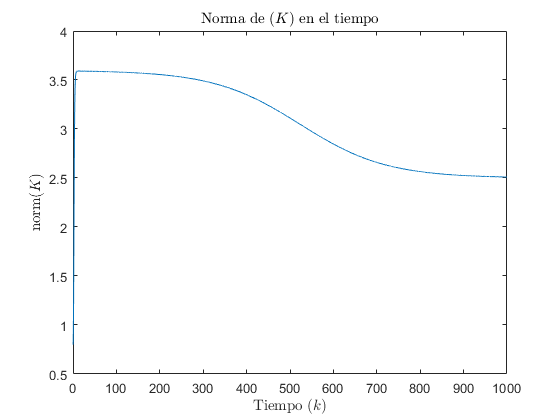


for k = 1:n-1
    
    % Estimación/Corrección de valores en k
    K = P_pre*C'/(C*P_pre*C'+N); % K(k) (factor de corrección de Kalman)
    x_act = x_pre + K*(y_sim(k) - C*x_pre); % x_hat(k|k)
    P = (I-K*C)*P_pre; % P(k), matriz de cov

    % Predicción de valores en k+1, se cambian dependiendo del caso
    x_pre = x_act + step*f(U(k+1),x_act(1),x_act(2), x_act(3)); % x_hat(k+1|k)
    A_k = A(U(k+1), x_act(1), x_act(2), x_act(3)); % Matriz A en la iteración actual
    P_pre = A_k*P*A_k'+V*M*V'; % P_bar(k+1), matriz de cov intermedia
    
    % Convergencia
    norma_K(k) = norm(K);
    x_hat(k,:) = x_act';
    traza_P(k) = trace(P);
    
end

% Visualización

% Norma de K
plot(t(1:end-1), norma_K);
title('Norma de $\mathcal(K)$ en el tiempo', 'interpreter','latex');
xlabel('Tiempo ($k$)', 'interpreter','latex');
ylabel('norm$\mathcal(K)$', 'interpreter','latex');

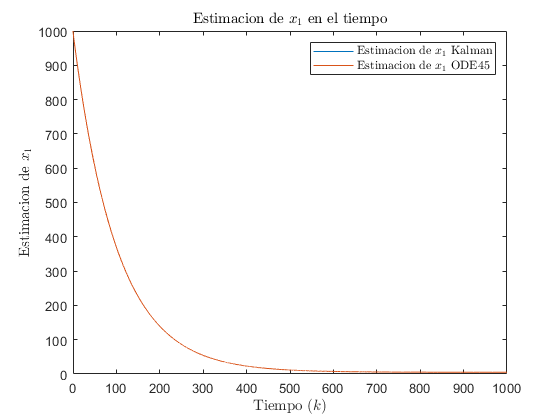

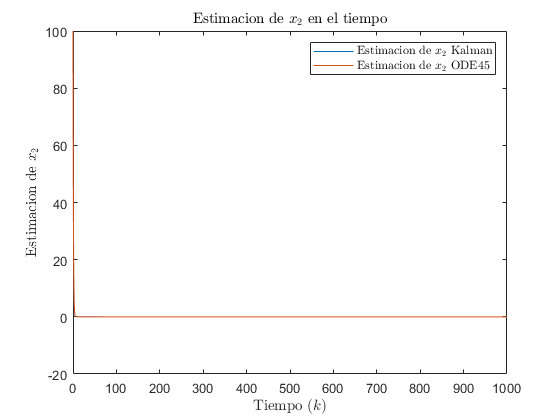

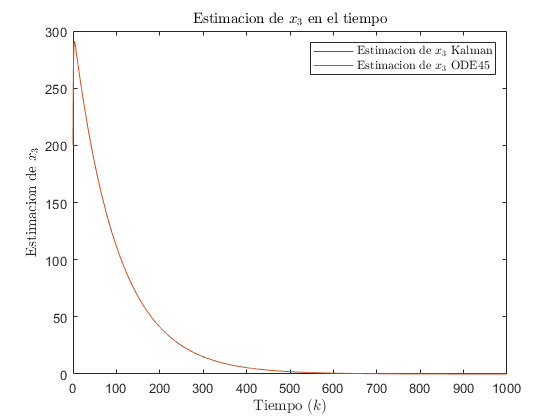


% Estimación Kalman vs simulada
for i=1:length(vars)
    figure()
    plot(t(1:end-1), x_hat(:,i));
    hold on
    plot(t(1:end-1), x_sim(1:end-1,i));
    title(sprintf('Estimacion de $x_%i$ en el tiempo', i), 'interpreter','latex');
    xlabel('Tiempo ($k$)', 'interpreter','latex');
    ylabel(sprintf('Estimacion de $x_%i$', i), 'interpreter','latex');
    legend(sprintf('Estimacion de $x_%i$ Kalman', i), ...
                   sprintf('Estimacion de $x_%i$ ODE45', i), 'interpreter','latex');
    hold off
end

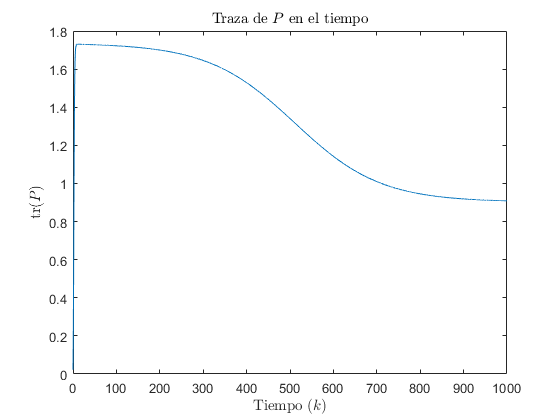


% Traza de P
plot(t(1:end-1), traza_P);
title('Traza de $P$ en el tiempo', 'interpreter','latex');
xlabel('Tiempo ($k$)', 'interpreter','latex');
ylabel('tr$(P)$', 'interpreter','latex');

function dxdt = ode(t,x,u,ut)
u = interp1(ut,u,t);
dxdt = zeros(3,1); % Cambiar dimensión 1 por número de variables de estados

Alpha = 0.05;
mu = 0.01;
beta= 0.05;
gamma = 0.07;

% Cambiar por las ecuaciones de estado del ejercicio
N = x(1) + x(2) + x(3);
dxdt(1) = Alpha - mu*x(1) - beta*x(2)*x(1)/N;
dxdt(2) = beta*x(2)*x(1)/N - (gamma+u)*x(2) -mu*x(2);
dxdt(3) = (gamma+u)*x(2) - mu*x(3);

end

function [t,x,y,u] = solve_ode(tspan,x0,u,C)
[t,x] = ode45(@(t,x) ode(t,x,u,tspan), tspan, x0);
y = x*C';
end